tic;
kx_step = 100;

kx = [-pi,pi];

kx_list = linspace(kx(1), kx(2),kx_step);
t = 1;
Length = 100;
Width = 10;
epsilon = 0;
mu = 0;
% sampling points of energy    
% energyscale = 4; 
% N_point = 101;
% omega = linspace(-energyscale,energyscale,N_point);
omega = -3.2;

fermilevel = omega;
energypoint = 1;

% Magnetic field
N_phi = 101;
% phi = linspace(0,0.25,N_phi);

phi = 0.5/(2*pi);

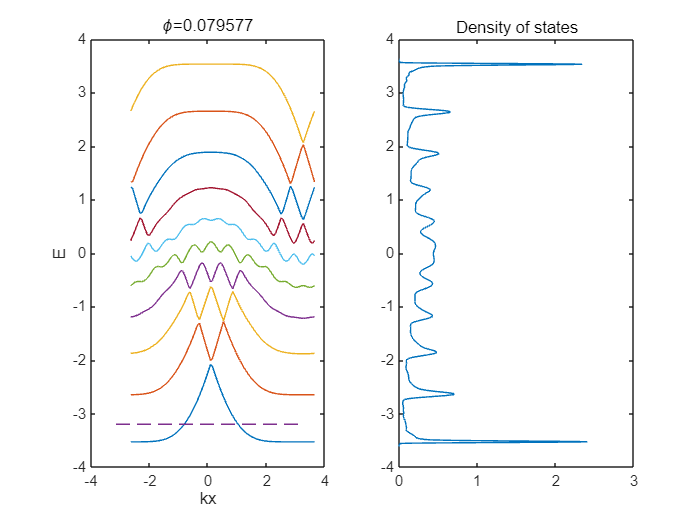


energy_band = zeros(kx_step, Width);
for jj = 1:length(phi)
    for ii = 1:length(kx_list)
        energy_band(ii, :) = eig(Hamiltonian_2D_Momentum_Bx(kx_list(ii), Width, mu, phi(jj), t));
    end
    subplot(1,2,1)
    plot(kx_list+phi*2*pi,energy_band, kx_list, fermilevel(energypoint)*ones(1,length(kx_list)),'--');
    title(['\phi=',num2str(phi(jj))])
    % pause(.1)
end
% axis([-3,3,-3,3])
xlabel('kx')
ylabel('E')
H = Hamiltonian_2D_Real(Length, Width, epsilon, phi, t);
subplot(1,2,2)
[energies_DOS, DOS] = KPM_DOS(H);
plot(DOS, energies_DOS)
title('Density of states')

% xscale log
toc;

历时 2.217527 秒。


% figure
% DOS_plot(eig(full(H)),40)
% axis([-3,3,0,1])
function H = Hamiltonian_2D_Real(Length, Width, epsilon, phi, t)
    
    H_00 = sparse(epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1));
    H_01 = sparse(-t * diag(exp(1i * 2*pi* (1:Width) * phi)));

    H = kron(speye(Length), H_00) + kron(spdiags(ones(Length, 1),1, Length, Length), H_01') + kron(spdiags(ones(Length, 1),-1, Length, Length), H_01);
    

end

function H = Hamiltonian_2D_Momentum_Bx(kx, Width, epsilon, phi, t)
    % Landau Gauge (0, Bx, 0)
    H_00 = epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1);
    H_01 = -t * diag(exp(1i * 2*pi * (1:Width) * phi));

    H = H_00 + exp(1i * kx) * H_01' + exp(-1i * kx) * H_01;

end

